# Frequency to Musical Note Conversion

Emirhan Taner   

Mehmet Seçkin Varol

Tolga Sarıyer

clc;        clear;        close all;

### File Path

% Select the file to be worked on
filePath = "/Users/emirhantaner/Desktop/Tech Writing/Kayitlar/12MakamdaYayli_tanbur_taksimleri/08_nihavend.mp3"

filePath = "/Users/emirhantaner/Desktop/Tech Writing/Kayitlar/12MakamdaYayli_tanbur_taksimleri/08_nihavend.mp3"

if filePath == ""
    filePath = "C:\Users\Atakan\Documents\MATLAB\IKU\12MakamdaYayli_tanbur_taksimleri\08_nihavend.mp3"
end


### Reading the Audio File

[audioData, fs] = audioread(filePath);

To see if the audio is mono or stereo, displaying the size of the audio Data. 

disp(size(audioData))

     9769620           2



The data is seen to be stereo since there are two channels.

### Visualizing the Audio

% declaring time axis to plot with
timeAxis = linspace(0,length(audioData)/fs,length(audioData))';

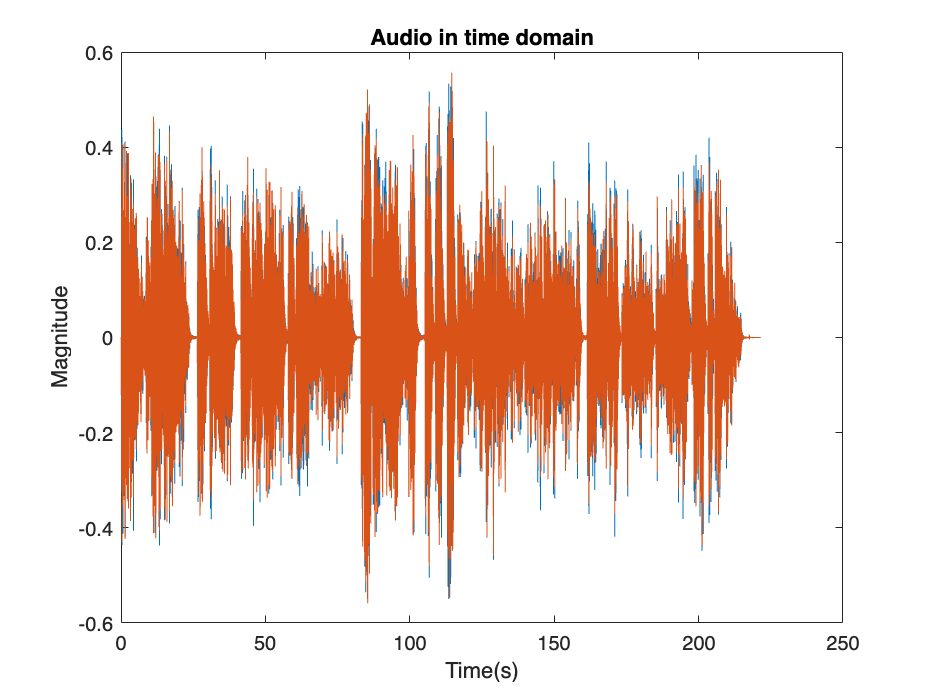


% plotting both of the channels together
figure;
plot(timeAxis,audioData)
title('Audio in time domain');
xlabel('Time(s)');
ylabel('Magnitude');

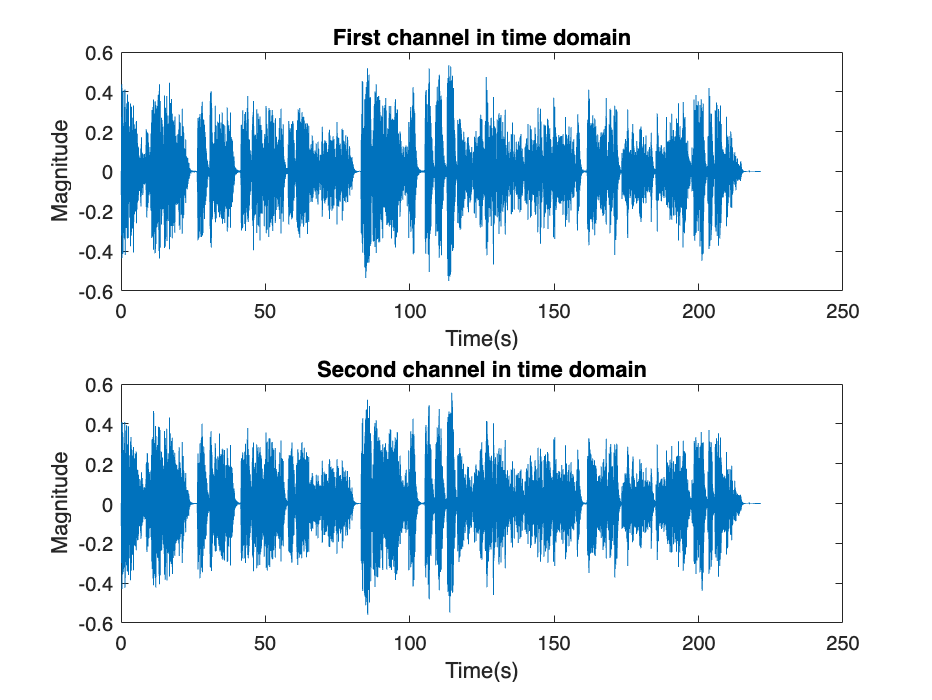


% declaring left and right channels
audioLeft = audioData(:,1);
audioRight = audioData(:,2);

% plotting the first(assuming left) channel
figure;
hold on;
subplot(2, 1, 1);
plot(timeAxis,audioLeft)
title('First channel in time domain');
xlabel('Time(s)');
ylabel('Magnitude');

% plotting the second(assuming right) channel
subplot(2, 1, 2);
plot(timeAxis,audioRight)
title('Second channel in time domain');
xlabel('Time(s)');
ylabel('Magnitude');
hold off;

### Taking the first 20 seconds of the audio, visualization

audioToProcess = audioLeft(1:20*fs);
% audioToProcess = audioRight(1:20*fs);

Redefining the time axis for visualization

timeAxis20 = linspace(0,length(audioToProcess)/fs,length(audioToProcess))';

Plotting the audio to be processed

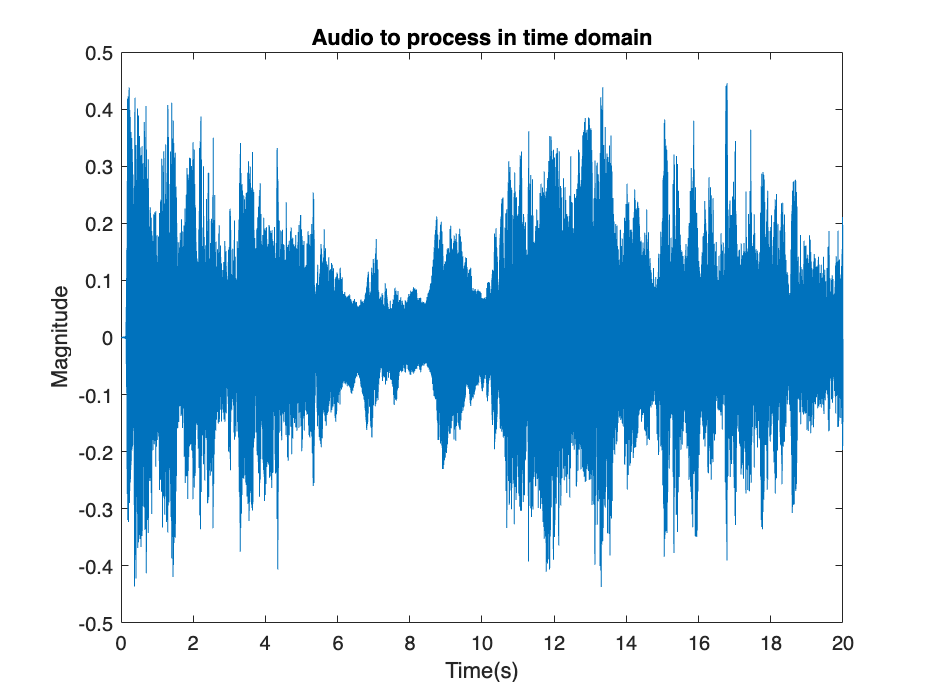

figure;
plot(timeAxis20,audioToProcess)
title('Audio to process in time domain');
xlabel('Time(s)');  
ylabel('Magnitude');

#### Clearing unnecessary variables

clear audioData audioRight audioLeft timeAxis filePath;

### Short-Time Fourier Transform

#### Parameters:

% Window size
% windowSize = 882;
windowSize = 4096;

**Window size** parameter is chosen as 882 samples. This means the windows are taken with 882 sample length. Equivalently, since sampling frequency is 44100, window size is (882 samples)/(44100 samples/seconds) = 1/50 seconds. Therefore we are taking stft with 0.02 second intervals.

% Window type
window = blackman(windowSize);

Lets see the effect of window types via the "Window Visualization Tool"

% wvtool(hann(windowSize), hamming(windowSize), rectwin(windowSize), ...
%     kaiser(windowSize), blackman(windowSize));
% % legend("hann","hamm","rect","kaiser","blackman");

% Number of overlap -hop size-
% nOverlap = 588;
nOverlap = 2048;


% N point DFT
nDFT = 4096;

#### Spectrogram Plots

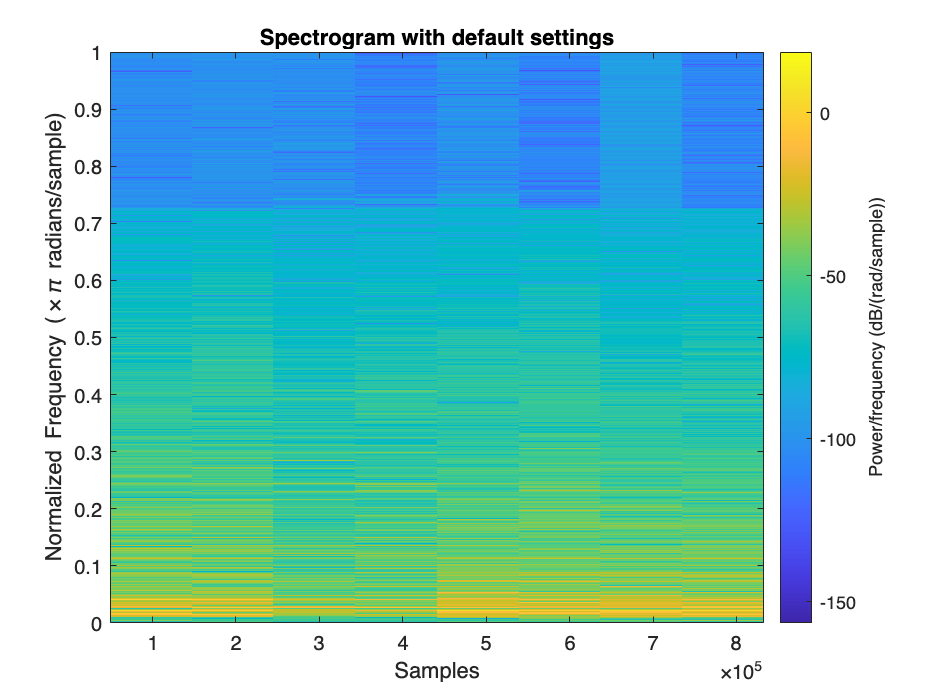

% spectrogram with default settings
figure;
spectrogram(audioToProcess, 'yaxis')
title('Spectrogram with default settings')

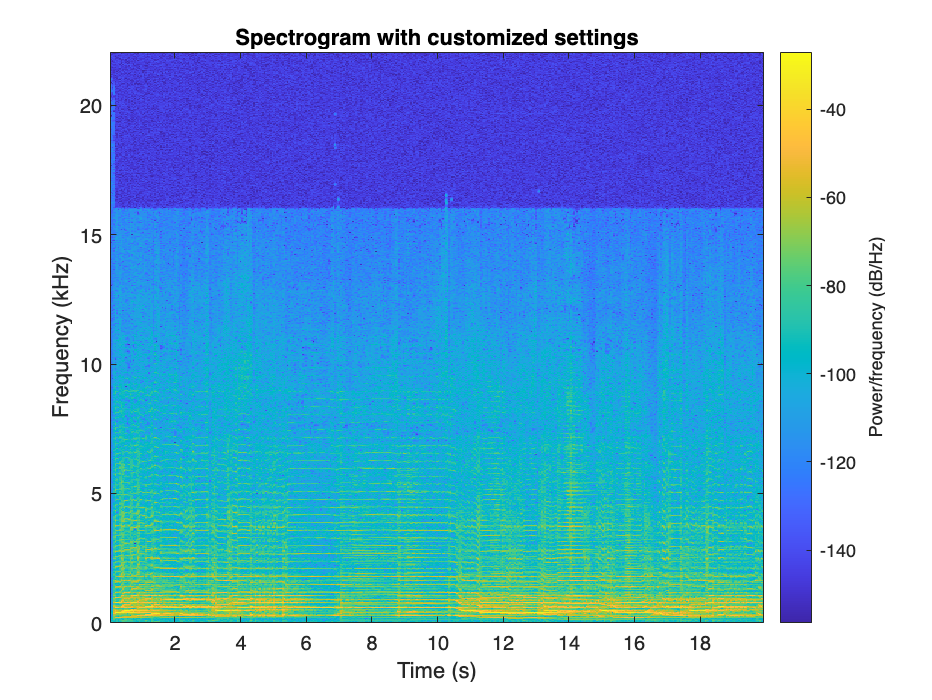


% spectrogram with the customized settings
figure;
spectrogram(audioToProcess, window, nOverlap, nDFT, fs, 'yaxis')
title('Spectrogram with customized settings')

3D Representation of Spectrogram

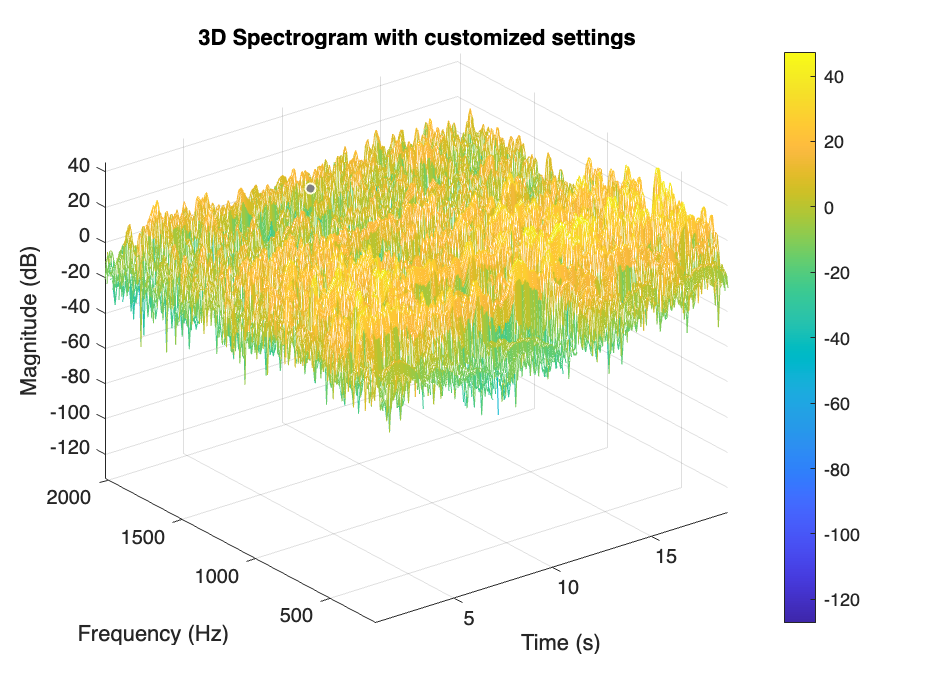

[specData, freqVector, timeVector] = spectrogram(audioToProcess, window, nOverlap, nDFT, fs, 'yaxis');
% Plotting the full spectrogram in 3D
plot3DSpectrogram(specData, timeVector, freqVector, [0,length(freqVector)])

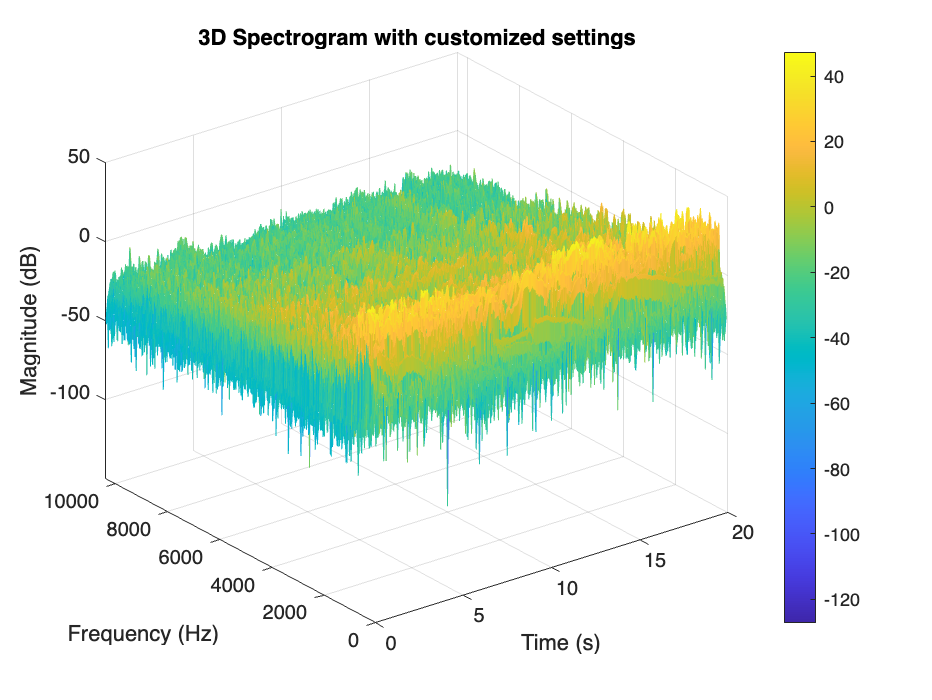

% Plotting the region of interest in 3D
freqLimitsToShow3D = [0,1e4];
plot3DSpectrogram(specData, timeVector, freqVector, freqLimitsToShow3D)

### Thresholding

Acquiring spectrogram data with selected parameters and show the spectrogram

[specData, freqVector, timeVector] = spectrogram(audioToProcess, window, nOverlap, nDFT, fs, 'yaxis');

Show spectrogram before threshold

% figure; 
% spectrogram(audioToProcess, window, nOverlap, nDFT, fs, 'yaxis'); 
% title('Spectrogram with selected parameters')

Apply threshold

threshold = 1;   % choosing an arbitrary threshold, can be experimented with
basicThresSpecData = applyThreshold(specData, threshold);

Display thresholded spectrogram

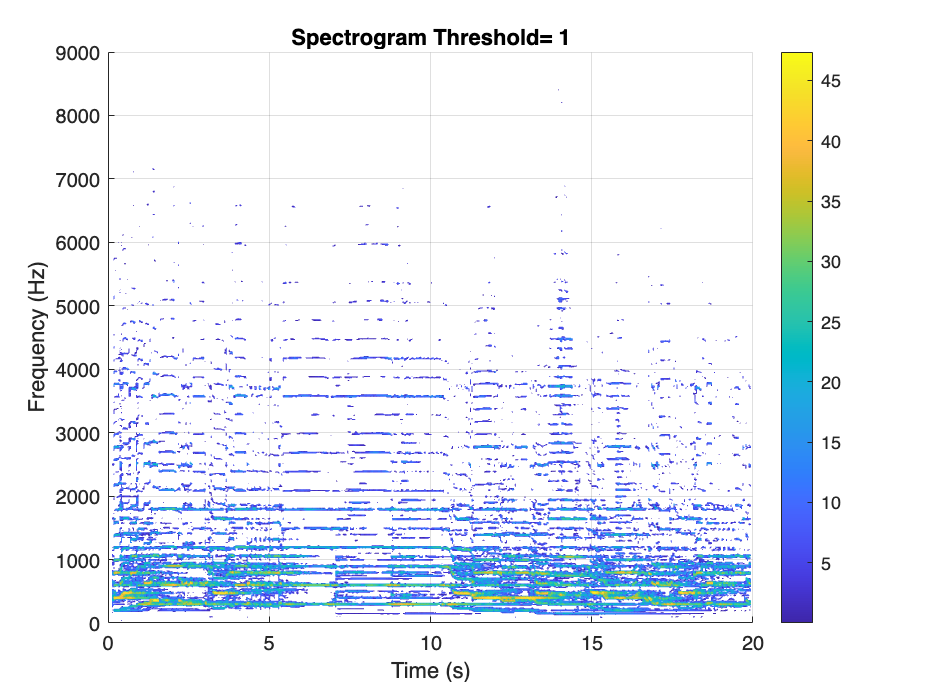

displayMeshSpectrogram(basicThresSpecData, timeVector, freqVector, threshold)

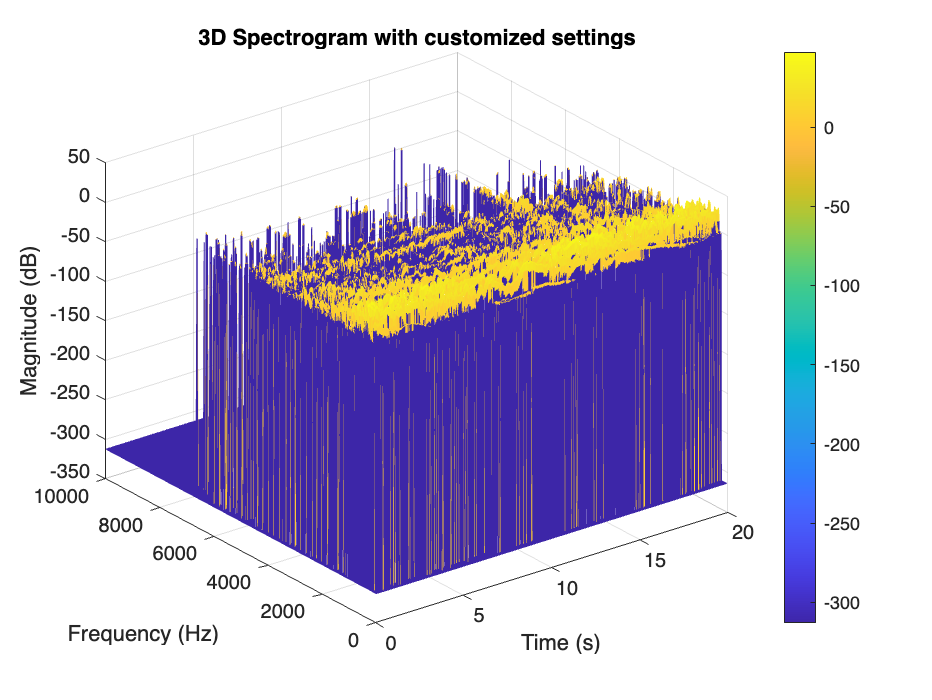


plot3DSpectrogram(basicThresSpecData, timeVector, freqVector, freqLimitsToShow3D)

### Applying Moving Average Filter

Parameters of filter

% Setting window sizes and axes for moving average filtering
movingAverageWindowSizeTime = 1;
movingAverageWindowSizeFreq = 5;
timeAxis = 1;
freqAxis = 2;

Apply moving average filter on time and frequency axes

specDataMA = applyMovingAverage(specData, movingAverageWindowSizeTime, timeAxis);
specDataMA = applyMovingAverage(specDataMA, movingAverageWindowSizeFreq, freqAxis);

### Thresholding

Apply threshold to filtered data

basicThresSpecData = applyThreshold(specDataMA, threshold);

Display thresholded spectrogram

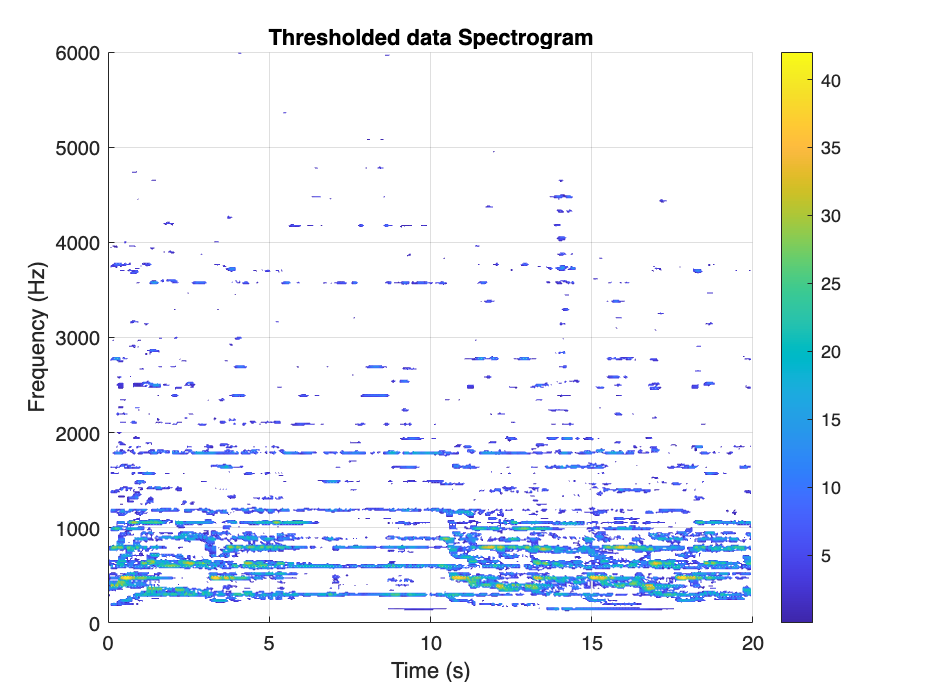

displayMeshSpectrogram(basicThresSpecData, timeVector, freqVector, threshold);
title('Thresholded data Spectrogram')

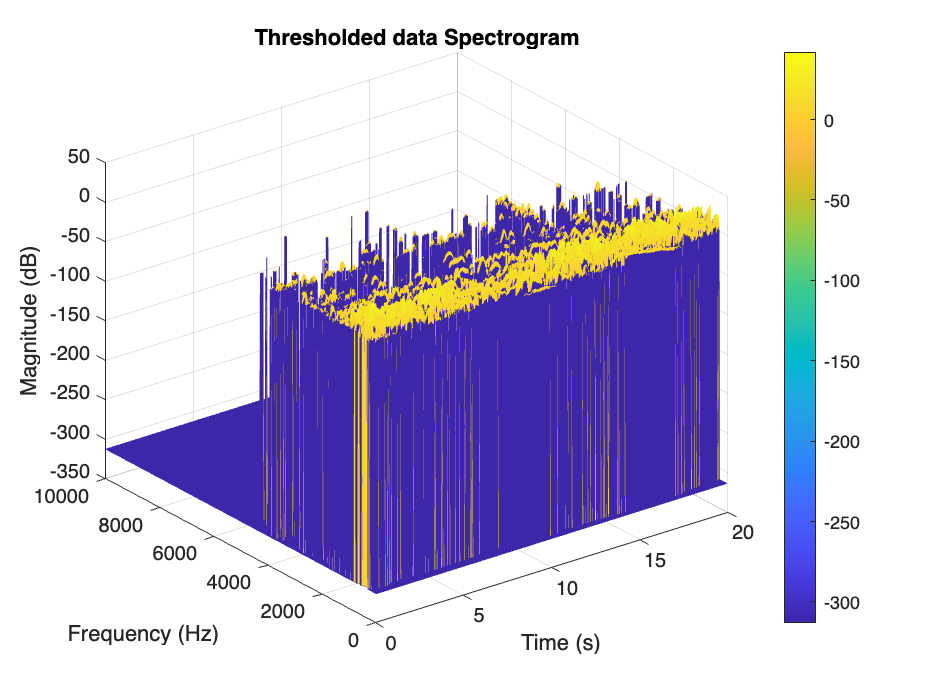


plot3DSpectrogram(basicThresSpecData, timeVector, freqVector, freqLimitsToShow3D)
title('Thresholded data Spectrogram')

### Find the peaks precisely and eliminate harmonics

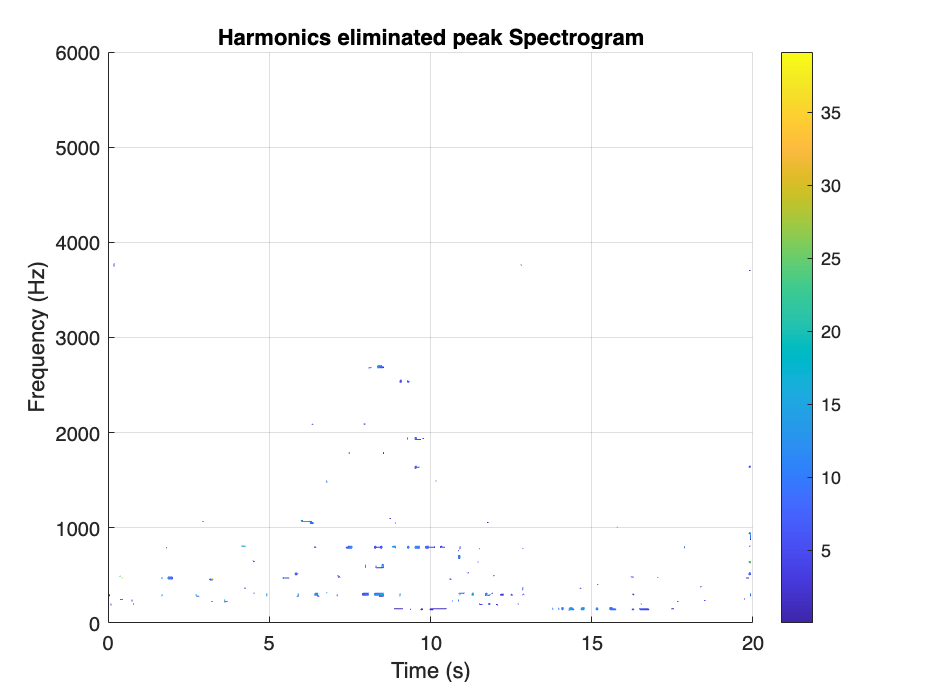

plotPeaks = false;
[peaks, peakLocations] = findFreqSpectrogramPeaks(basicThresSpecData, fs, plotPeaks);

numHarmonics = 7;
frequencyMarginToEliminate = 2;
eliminatedSpecData = eliminateHarmonics(basicThresSpecData, ...
                                        peaks, ...
                                        peakLocations, ...
                                        freqVector, ...
                                        numHarmonics, ...
                                        frequencyMarginToEliminate);

% Plot the spectrogram
displayMeshSpectrogram(eliminatedSpecData, timeVector, freqVector, threshold);
title('Harmonics eliminated peak Spectrogram');

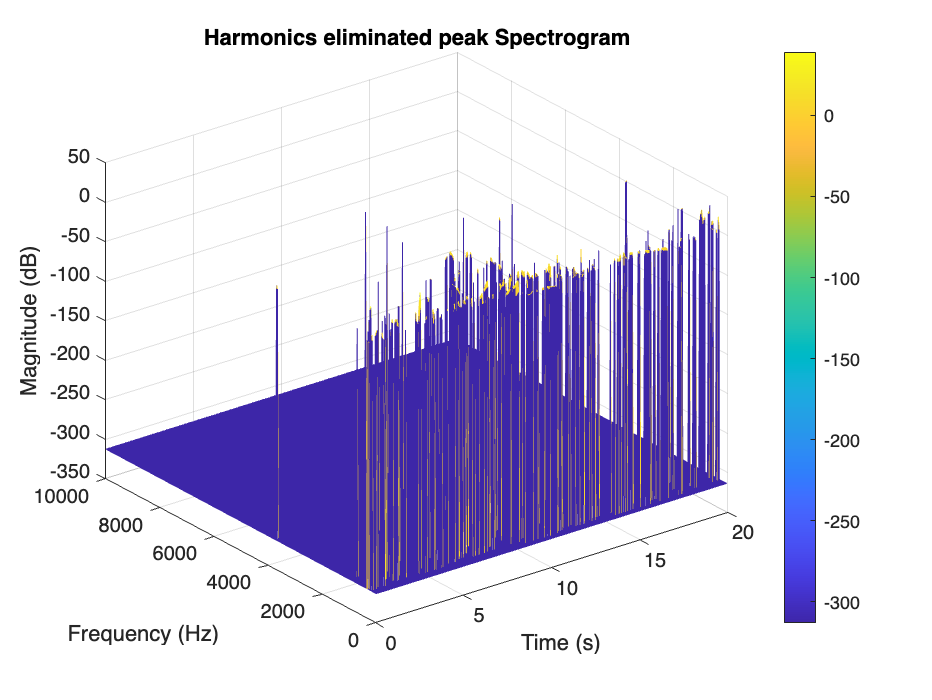


plot3DSpectrogram(eliminatedSpecData, timeVector, freqVector, freqLimitsToShow3D)
title('Harmonics eliminated peak Spectrogram')

### Conversion to MIDI numbers

Creating MIDI number vector 

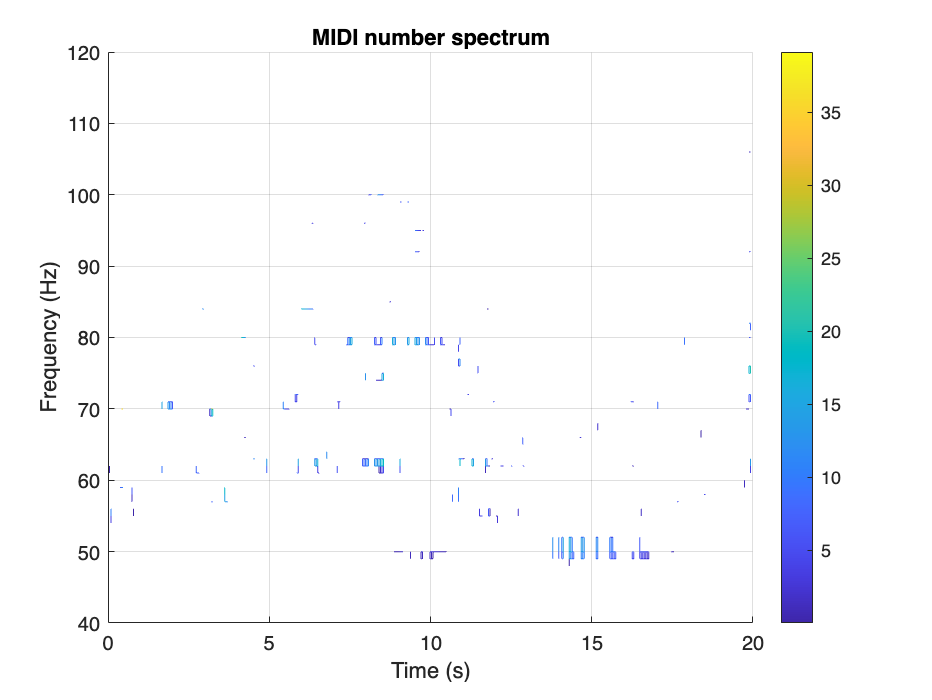

midiNumberVector = zeros(length(eliminatedSpecData(:,1)),1);
midiNumberVector = [0; round(12.*(log2(freqVector(2:length(freqVector))./440))+69)];

% Displaying the Spectrogram with MIDI numbers instead of frequencies
displayMeshSpectrogram(eliminatedSpecData, timeVector, midiNumberVector, threshold);
title('MIDI number spectrum');

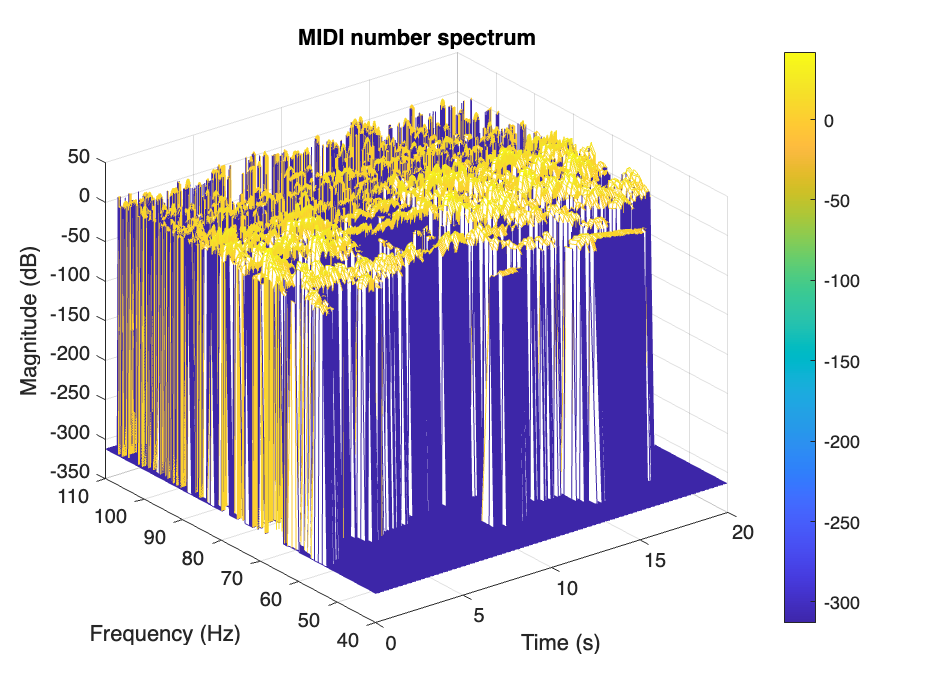



plot3DSpectrogram(basicThresSpecData, timeVector, midiNumberVector, [40,110])
title('MIDI number spectrum')

### Plot scatter plot with MIDI numbers

minMidi = 0;
maxMidi = 120;

Scatter plot of harmonic eliminated data

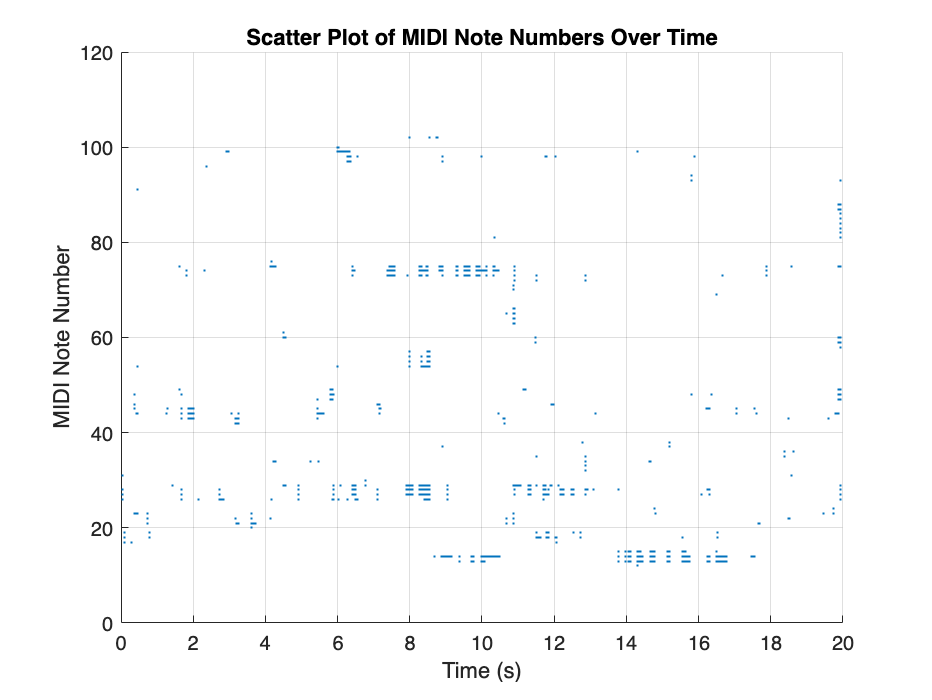

plotMidiScatter(eliminatedSpecData, timeVector, minMidi, maxMidi, threshold);

Scatter plot of thresholded data

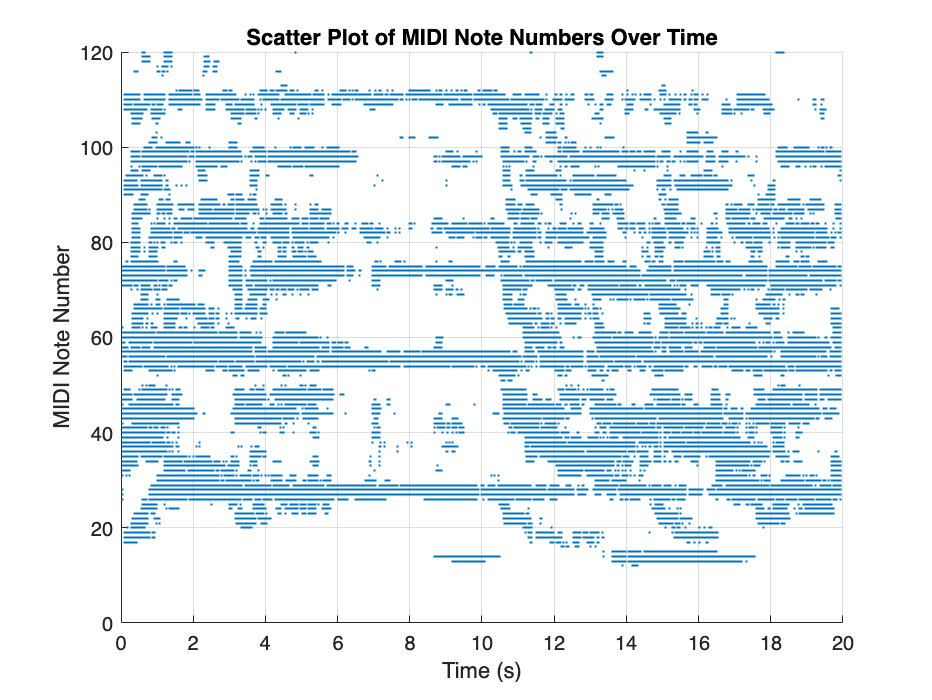

plotMidiScatter(basicThresSpecData, timeVector, minMidi, maxMidi, threshold);

Scatter plot of only the maximum values only thresholded data

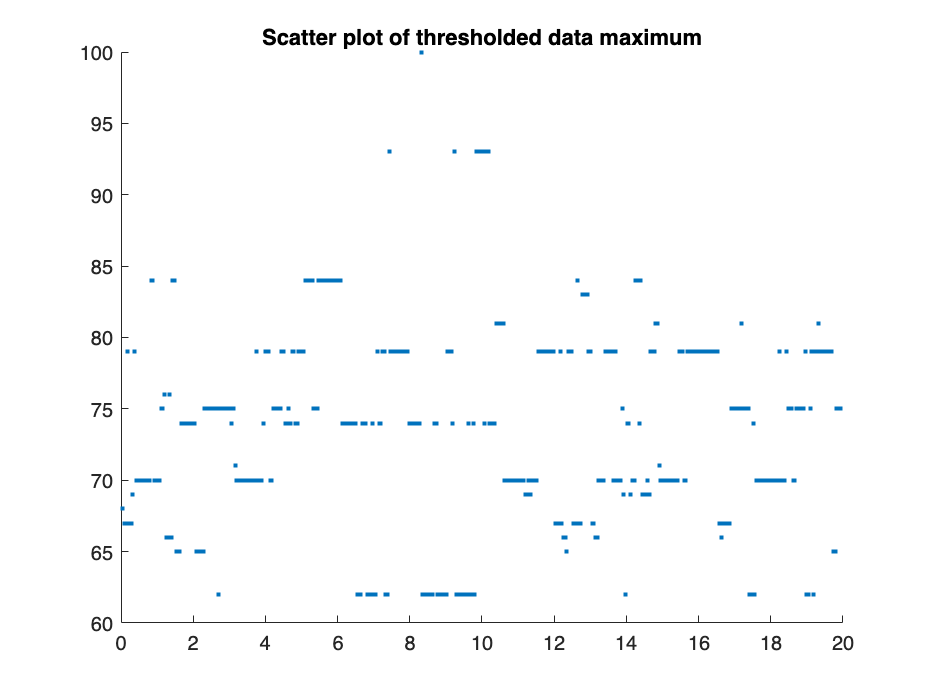

[midiMax, maxIdx] = max(basicThresSpecData);
figure; 
scatter(timeVector,midiNumberVector(maxIdx),'.');
title('Scatter plot of thresholded data maximum');

Scatter plot of only the maximum values for harmonics eliminated data

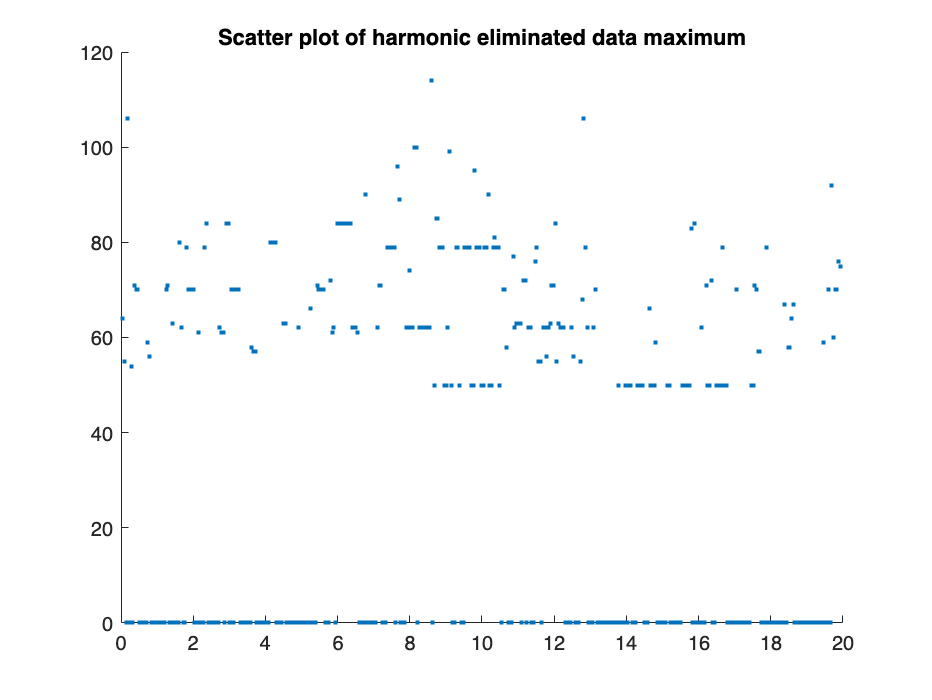

[midiMax, maxIdx] = max(eliminatedSpecData);
figure; 
scatter(timeVector,midiNumberVector(maxIdx),'.');
title('Scatter plot of harmonic eliminated data maximum');

**Note: **From these plots we can see that maximum values plot is more suitable for our purposes, but we need to increase the threshold. Then put another layer, maybe more than one, using the same principles we used before.

Redoing the prodecure with different threshold values to determine the first layer

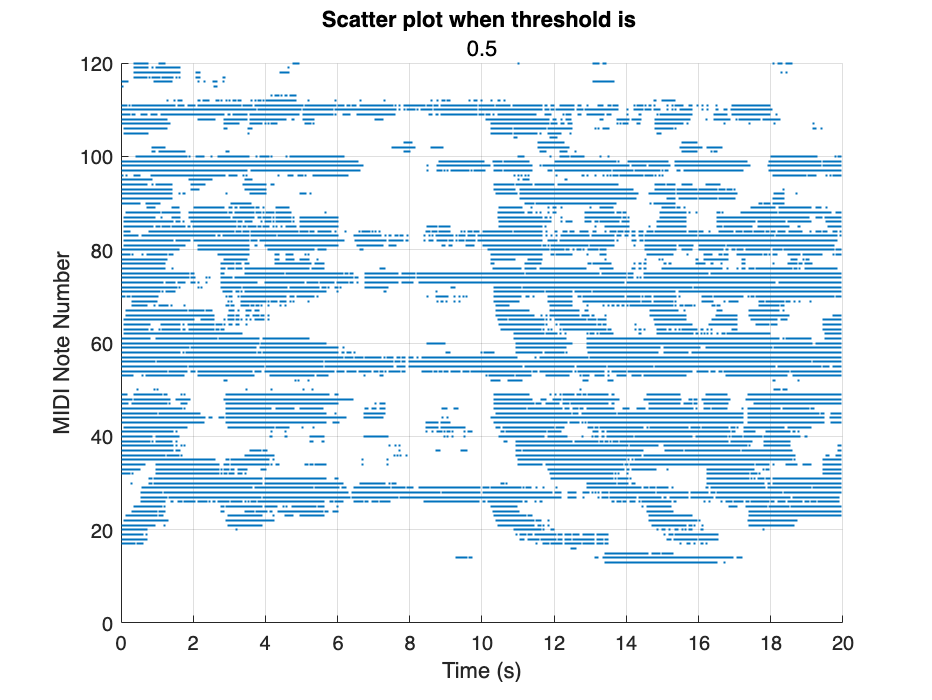

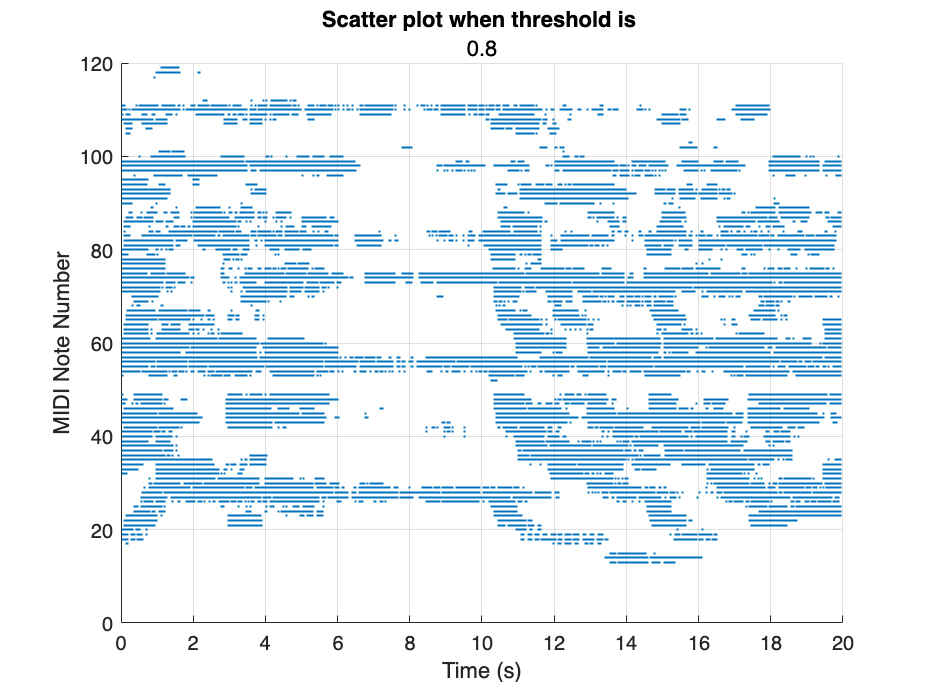

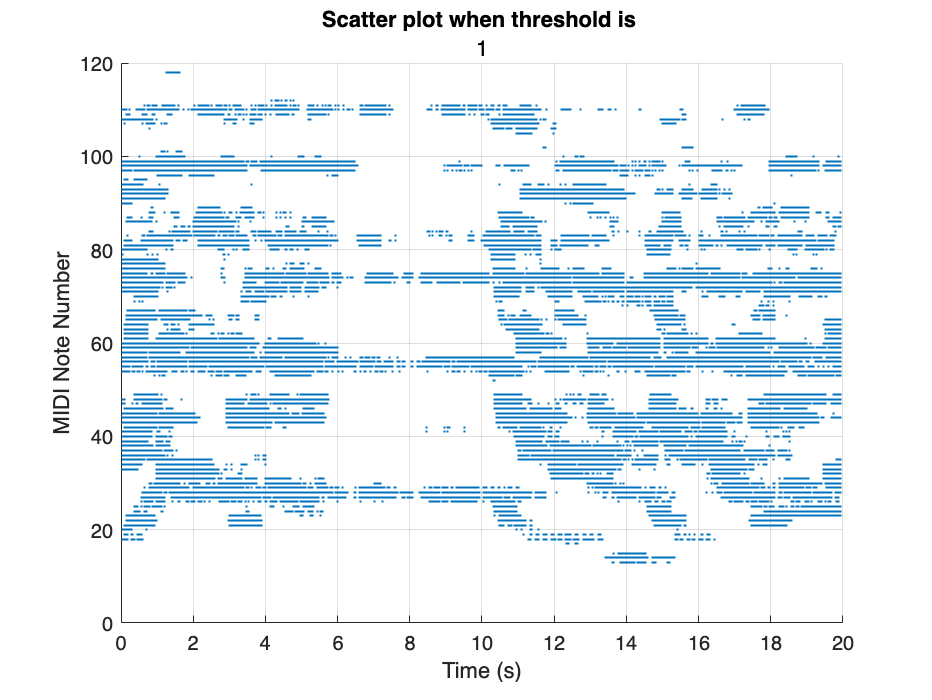

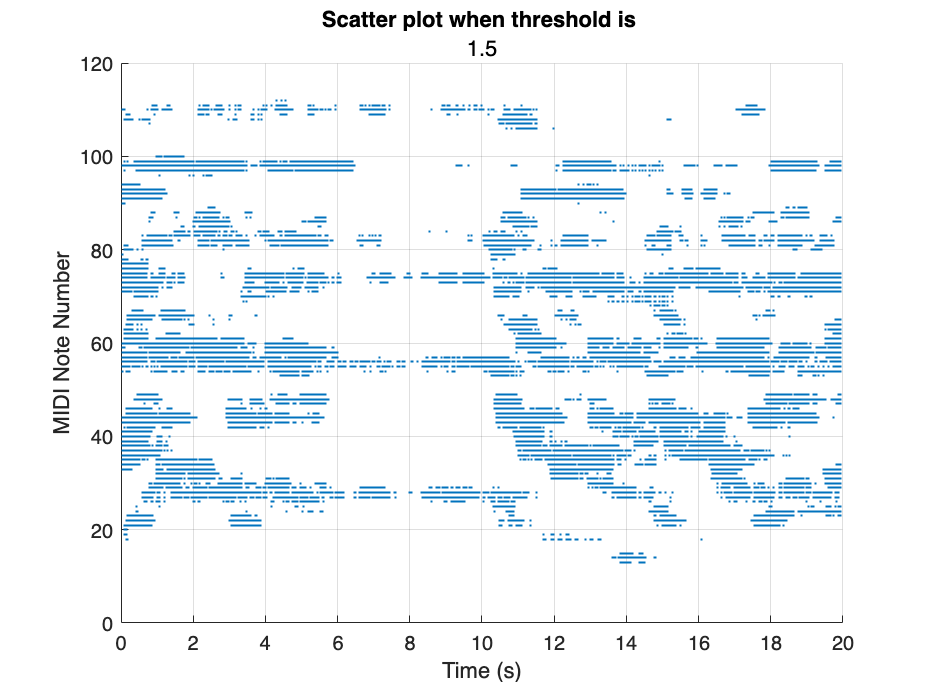

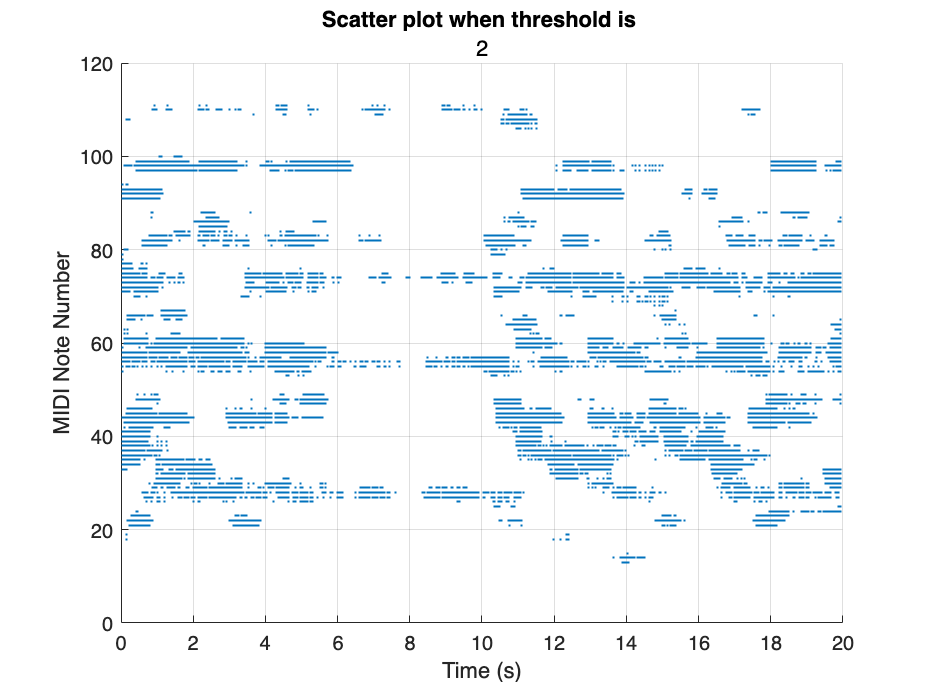

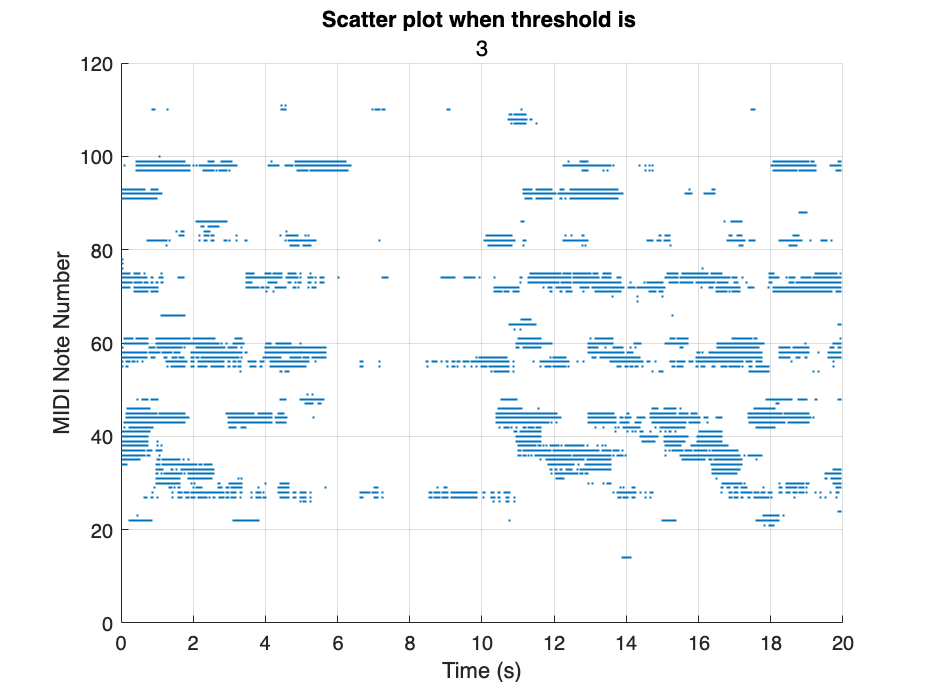

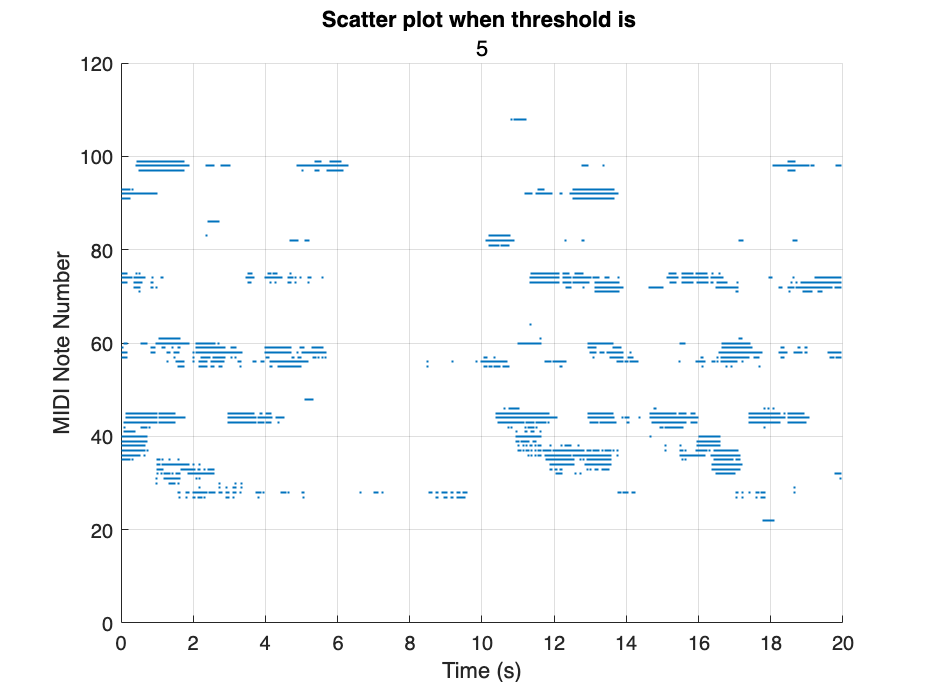

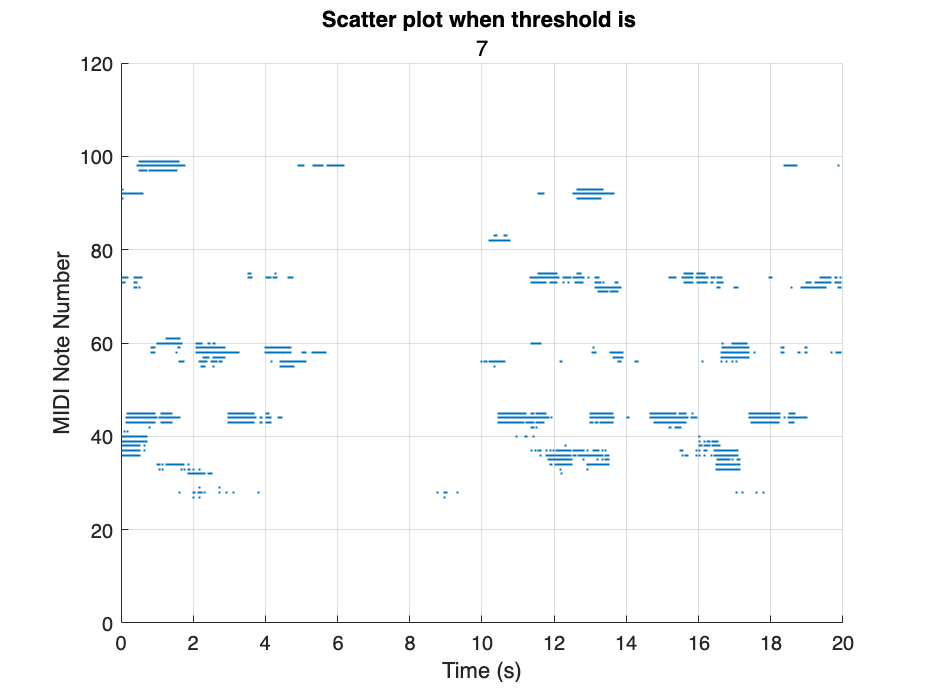

experimentThreshold = [0.5, 0.8, 1, 1.5, 2, 3, 5, 7, 10, 12, 15, 20];
movingAverageWindowSizeFreq = 15;
for threshold=experimentThreshold
    specDataMA = applyMovingAverage(specData, movingAverageWindowSizeFreq, freqAxis);
    basicThresSpecData = applyThreshold(specDataMA, threshold);
    plotMidiScatter(basicThresSpecData, timeVector, minMidi, maxMidi, threshold);
    title('Scatter plot when threshold is ', num2str(threshold));
end

It is shown that thresholding with 0.5 is not thresholding enough, on the other hand thresholding with more than 15 seems to eliminate too much. Therefore let us try the next layers when threshold is set to 15 and 10 by layers.

### Multi-Layered Plots

#### The first layer

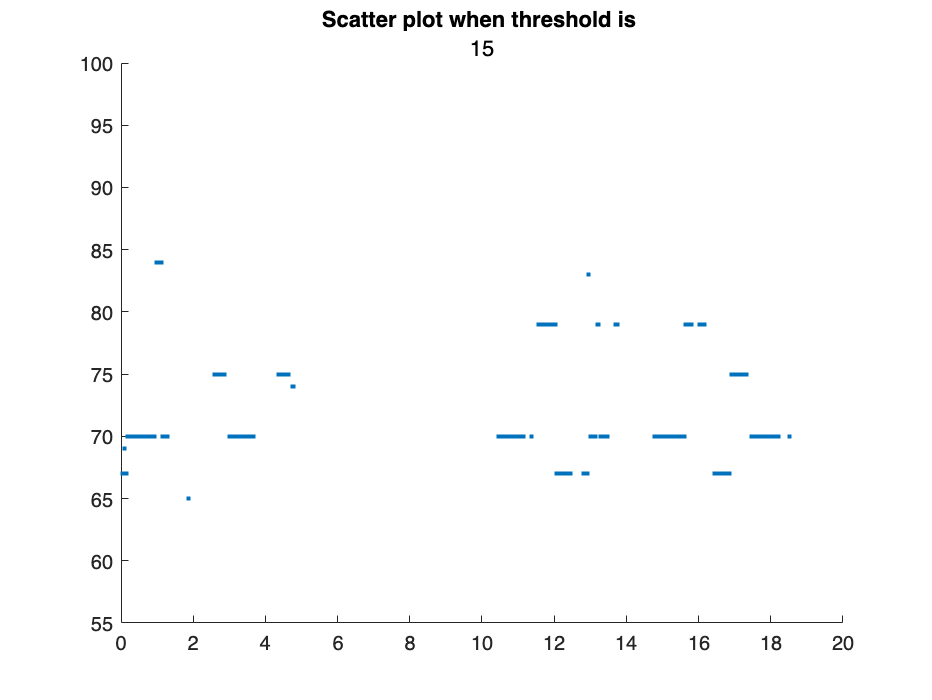

threshold = 15;
movingAverageWindowSizeFreq = 15;
specDataMA = applyMovingAverage(specData, movingAverageWindowSizeFreq, freqAxis);
basicThresSpecData = applyThreshold(specDataMA, threshold);
[midiMax1, maxIdx1] = max(basicThresSpecData);
figure; scatter(timeVector,midiNumberVector(maxIdx1),'.');
title('Scatter plot when threshold is ', num2str(threshold));
ylim([55, 100]);


% Lets check how many entries of timeVector is plotted on the first layer
sum(midiMax>0)

ans = 218

Eliminate Harmonics from the first layer

% Eliminating harmonics that are used in the first layer
numHarmonics = 7;
frequencyMarginToEliminate = 2;
% Elimination peak location set to the ones that are used
[peaks, peakLocations] = findFreqSpectrogramPeaks(basicThresSpecData, fs, plotPeaks);
% peakLocations = num2cell(maxIdx, 2);
eliminatedSpecData = eliminateHarmonics(specDataMA, ...
                                        peaks, ...
                                        peakLocations, ...
                                        freqVector, ...
                                        numHarmonics, ...
                                        frequencyMarginToEliminate);

#### The second layer

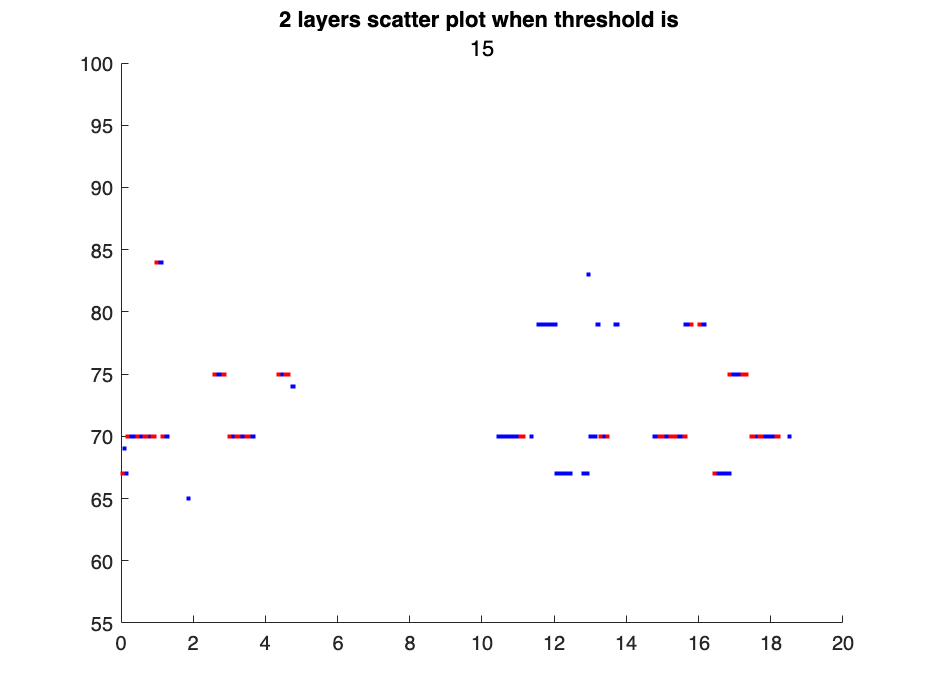

basicThresSpecData = applyThreshold(eliminatedSpecData, threshold);
[midiMax2, maxIdx2] = max(basicThresSpecData);
figure; 
scatter(timeVector,midiNumberVector(maxIdx1),'.','b'); 
hold on;
scatter(timeVector,midiNumberVector(maxIdx2),'.', 'r'); 
hold off;
title('2 layers scatter plot when threshold is ', num2str(threshold));
ylim([55, 100]);

Eliminate Harmonics from the second layer

% Eliminating harmonics that are used in the first layer
numHarmonics = 7;
frequencyMarginToEliminate = 2;
% Elimination peak location set to the ones that are used
[peaks, peakLocations] = findFreqSpectrogramPeaks(basicThresSpecData, fs, plotPeaks);
eliminatedSpecData = eliminateHarmonics(eliminatedSpecData, ...
                                        peaks, ...
                                        peakLocations, ...
                                        freqVector, ...
                                        numHarmonics, ...
                                        frequencyMarginToEliminate);

#### The third layer

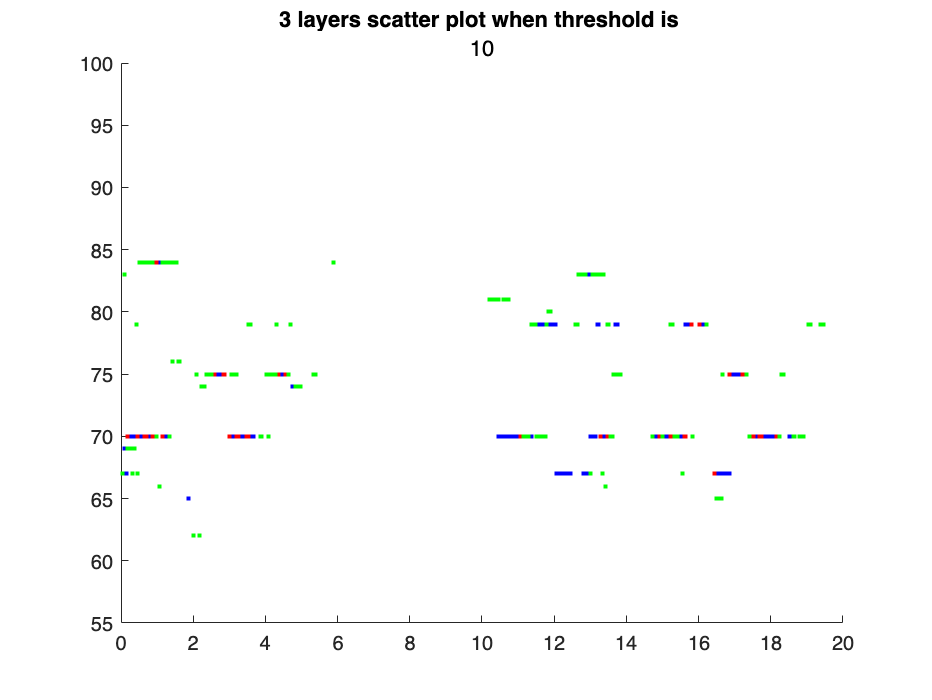

threshold = 10;
basicThresSpecData = applyThreshold(eliminatedSpecData, threshold);
[midiMax3, maxIdx3] = max(basicThresSpecData);
figure; 
scatter(timeVector,midiNumberVector(maxIdx1),'.','b'); 
hold on;
scatter(timeVector,midiNumberVector(maxIdx2),'.', 'r'); 
scatter(timeVector,midiNumberVector(maxIdx3),'.', 'g'); 
hold off;
title('3 layers scatter plot when threshold is ', num2str(threshold));
ylim([55, 100]);

Eliminate Harmonics from the third layer

% Eliminating harmonics that are used in the first layer
numHarmonics = 7;
frequencyMarginToEliminate = 2;
% Elimination peak location set to the ones that are used
[peaks, peakLocations] = findFreqSpectrogramPeaks(basicThresSpecData, fs, plotPeaks);
eliminatedSpecData = eliminateHarmonics(eliminatedSpecData, ...
                                        peaks, ...
                                        peakLocations, ...
                                        freqVector, ...
                                        numHarmonics, ...
                                        frequencyMarginToEliminate);

#### The fourth layer

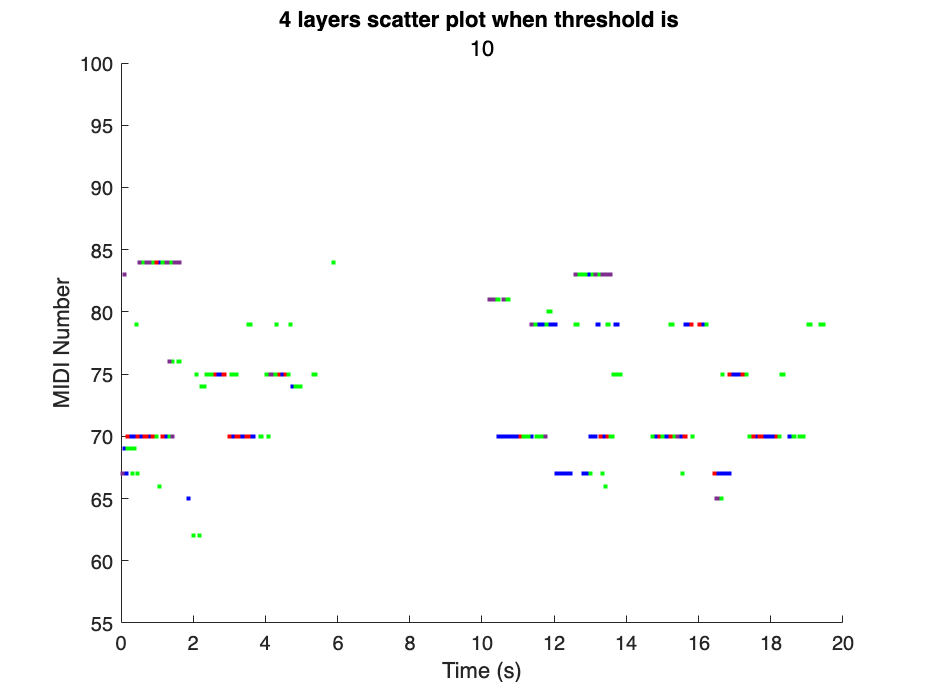

basicThresSpecData = applyThreshold(eliminatedSpecData, threshold);
[midiMax4, maxIdx4] = max(basicThresSpecData);
figure; 
scatter(timeVector,midiNumberVector(maxIdx1),'.','b'); 
hold on;
scatter(timeVector,midiNumberVector(maxIdx2),'.', 'r'); 
scatter(timeVector,midiNumberVector(maxIdx3),'.', 'g'); 
scatter(timeVector,midiNumberVector(maxIdx4),'.', 'p'); 
xlabel('Time (s)');
ylabel('MIDI Number');
hold off;
title('4 layers scatter plot when threshold is ', num2str(threshold));
ylim([55, 100]);

#### Merge these scatter plots

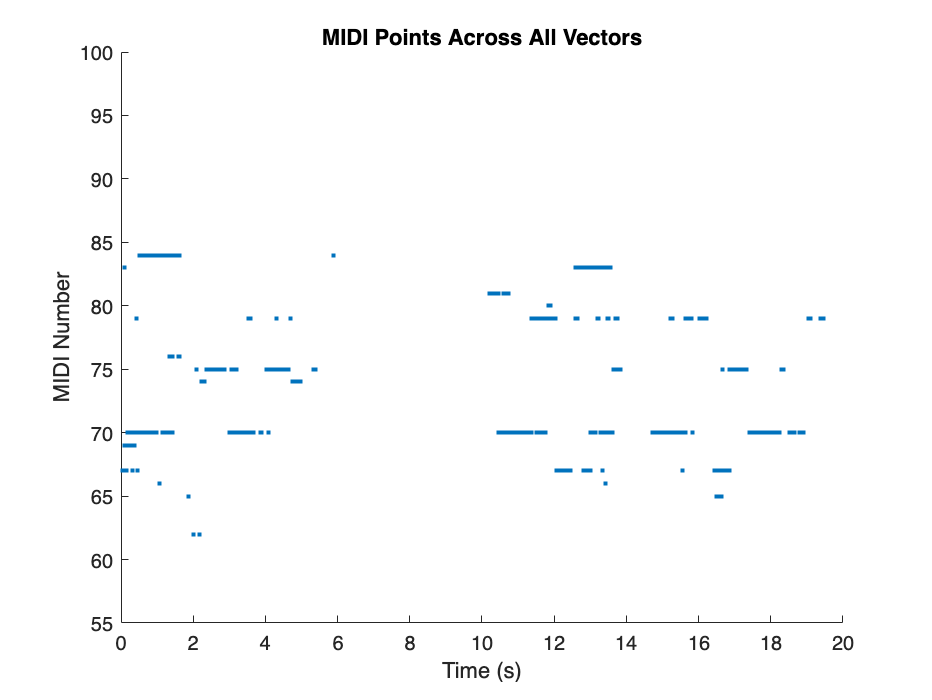

minNumOfPoints = 2;
numberOfPointsToCheck = 5;
timeResolution = 20/length(timeVector); 
timeThreshold = numberOfPointsToCheck * timeResolution;

[filteredTime, filteredMidi] = filterIsolatedPointsAcrossVectors({timeVector, timeVector, timeVector, timeVector}, ...
    {midiNumberVector(maxIdx1), midiNumberVector(maxIdx2), midiNumberVector(maxIdx3), midiNumberVector(maxIdx4)}, ...
    timeThreshold);

figure;
scatter(filteredTime, filteredMidi, '.');
title('MIDI Points Across All Vectors');
xlabel('Time (s)');
ylabel('MIDI Number');
ylim([55, 100]);

#### Eliminate single points

Let us do some experiments to smooth the plot from singular points

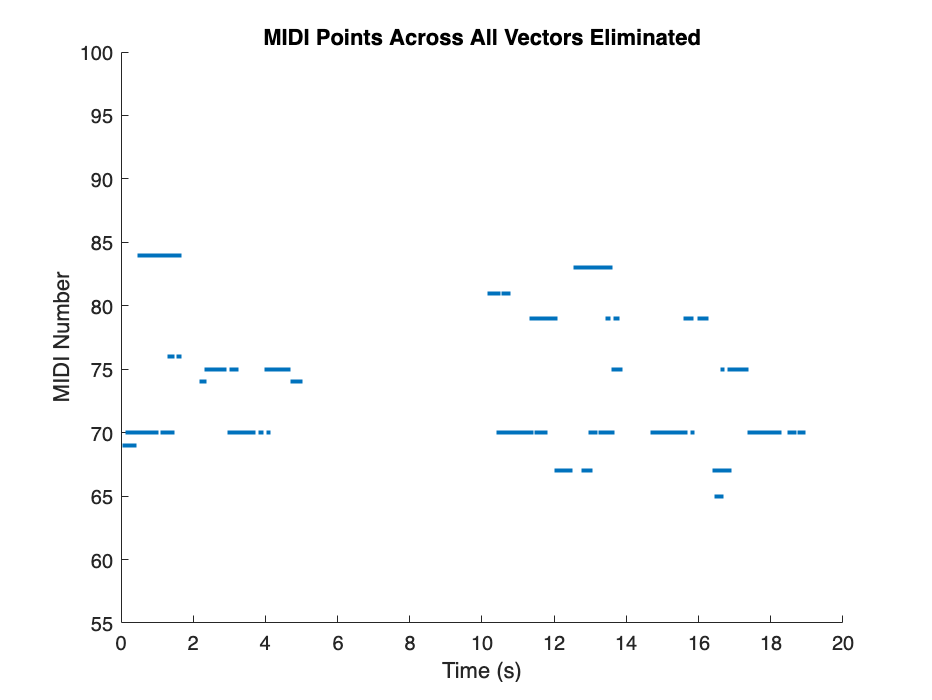

% when 2 point is needed out of every 5
minNumOfPoints = 2;
numberOfPointsToCheck = 5;
timeResolution = 20/length(timeVector); 
timeThreshold = numberOfPointsToCheck * timeResolution;

refinedMidi = refineMidiEntries(filteredTime, filteredMidi, timeThreshold, minNumOfPoints);
figure;
scatter(filteredTime, refinedMidi, '.');
title('MIDI Points Across All Vectors Eliminated');
xlabel('Time (s)');
ylabel('MIDI Number');
ylim([55, 100]);

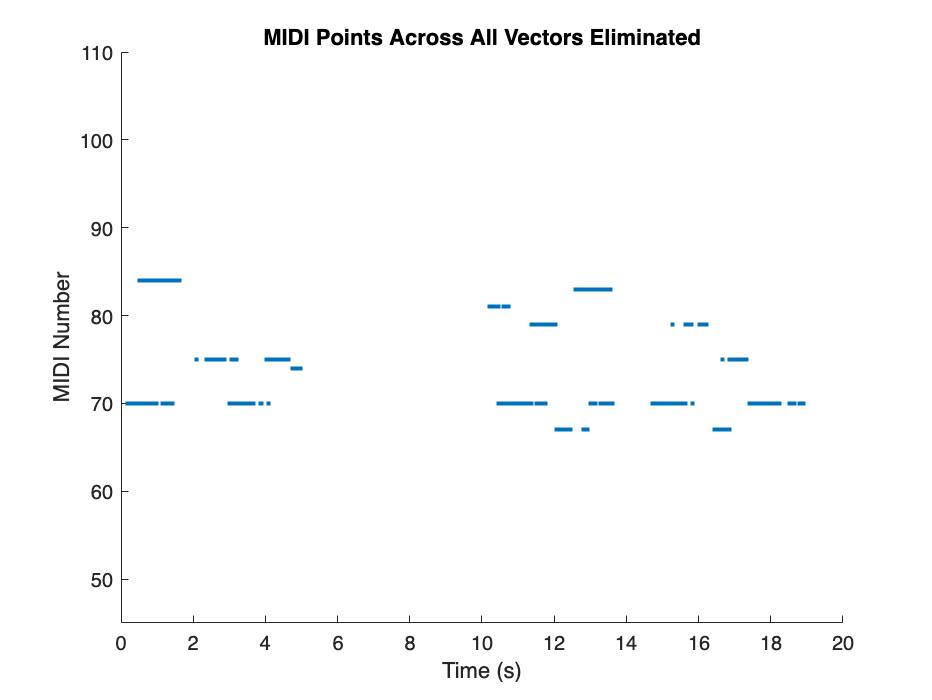


% when 5 point is needed out of every 11
minNumOfPoints = 5;
numberOfPointsToCheck = 11;
timeResolution = 20/length(timeVector); 
timeThreshold = numberOfPointsToCheck * timeResolution;

refinedMidi = refineMidiEntries(filteredTime, filteredMidi, timeThreshold, minNumOfPoints);
figure;
scatter(filteredTime, refinedMidi, '.');
title('MIDI Points Across All Vectors Eliminated');
xlabel('Time (s)');
ylabel('MIDI Number');
ylim([45, 110]);

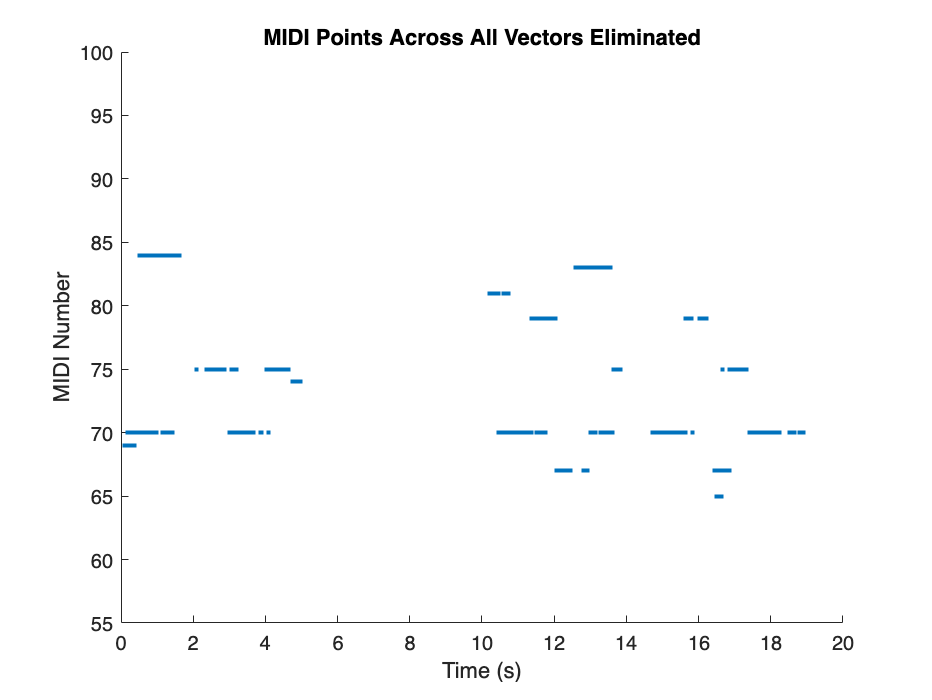


% when 4 point is needed out of every 10
minNumOfPoints = 4;
numberOfPointsToCheck = 10;
timeResolution = 20/length(timeVector); 
timeThreshold = numberOfPointsToCheck * timeResolution;

refinedMidi = refineMidiEntries(filteredTime, filteredMidi, timeThreshold, minNumOfPoints);
figure;
scatter(filteredTime, refinedMidi, '.');
title('MIDI Points Across All Vectors Eliminated');
xlabel('Time (s)');
ylabel('MIDI Number');
ylim([55, 100]);

This plot seems to give the best result. 

The following are the functions that are utilized above.

function thresholdedSpectrogram = applyThreshold(spectrogramData, threshold)
    % applyThreshold - Apply a magnitude threshold to spectrogram data
    %
    % Syntax:  thresholdedSpectrogram = applyThreshold(spectrogramData, threshold)
    %
    % Inputs:
    %    spectrogramData - Complex spectrogram data (output from spectrogram function)
    %    threshold - Magnitude threshold level (scalar)
    %
    % Outputs:
    %    thresholdedSpectrogram - Spectrogram with applied threshold

    % Calculate the magnitude of the spectrogram
    magnitudeSpectrogram = abs(spectrogramData);
    
    % Apply the threshold
    magnitudeSpectrogram(magnitudeSpectrogram < threshold) = 0;
    
    % % Maintain the phase information of the original spectrogram
    % phaseSpectrogram = angle(spectrogramData);
    
    % % Reconstruct the thresholded spectrogram data
    % thresholdedSpectrogram = magnitudeSpectrogram .* exp(1i * phaseSpectrogram);
    thresholdedSpectrogram = magnitudeSpectrogram;
end


function displayMeshSpectrogram(mtv1, t_spec, f_spec, threshold)
    % displayMeshSpectrogram - Display a 2D view mesh plot of spectrogram data
    %
    % Syntax:  displayMeshSpectrogram(mtv1, t_spec, f_spec, threshold)
    %
    % Inputs:
    %    mtv1 - Spectrogram data matrix (complex or real)
    %    t_spec - Time vector for the spectrogram data
    %    f_spec - Frequency vector for the spectrogram data
    %    threshold - Threshold value used for display in the title
    %
    % Outputs:
    %    A figure window with a 2D view mesh plot of the spectrogram data

    % Create a new figure
    figure;
    
    % Convert magnitude of spectrogram data to dB
    sdb = mag2db(abs(mtv1));  % Add eps to avoid log of zero

    % Create a mesh plot only showing the thresholded values with (1,:)
    mesh(t_spec(1,:), f_spec(:,1), sdb);
    
    % Set view to 2D
    view(2);
    
    % Add colorbar to the plot
    colorbar;
    
    % Set title with the threshold value
    title(['Spectrogram Threshold= ', num2str(threshold)]);
    
    % Label axes
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    zlabel('Magnitude (dB)');
end


function filteredSpectrogram = applyMovingAverage(S, windowSize, dim)
    % applyMovingAverage - Apply a moving average filter to spectrogram data
    %
    % Syntax:  filteredSpectrogram = applyMovingAverage(S, windowSize, dim)
    %
    % Inputs:
    %    S - Spectrogram data matrix (real or complex)
    %    windowSize - Size of the moving average window (scalar)
    %    dim - Dimension along which to apply the filter (1 for frequency, 2 for time)
    %
    % Outputs:
    %    filteredSpectrogram - Spectrogram data after applying the moving average filter

    % Check if input data is real or complex
    if isreal(S)
        % Apply moving average filter to real data
        filteredSpectrogram = movmean(S, windowSize, dim);
    else
        % For complex data, apply the filter separately to the real and imaginary parts
        realPart = movmean(real(S), windowSize, dim);
        imagPart = movmean(imag(S), windowSize, dim);
        filteredSpectrogram = realPart + 1i * imagPart;
    end
end


function [peaks, peakLocs] = findFreqSpectrogramPeaks(S, fs, plotFlag)
    % findFreqSpectrogramPeaks - Find and optionally plot peaks in spectrogram data
    %
    % Syntax:  [peaks, peakLocs] = findFreqSpectrogramPeaks(S, fs, plotFlag)
    %
    % Inputs:
    %    S - Spectrogram data matrix (output of MATLAB's spectrogram function)
    %    fs - Sampling frequency of the original signal
    %    plotFlag - Boolean flag to control plotting (true for plotting, false otherwise)
    %
    % Outputs:
    %    peaks - Cell array containing peak values for each frequency band
    %    peakLocs - Cell array containing peak locations for each frequency band

    % Convert complex spectrogram to magnitude
    magnitudeSpectrogram = abs(S);

    % Initialize outputs
    numFreqBands = size(S, 1);
    peaks = cell(numFreqBands, 1);
    peakLocs = cell(numFreqBands, 1);

    % Find peaks for each frequency band
    for i = 1:numFreqBands
        [peaks{i}, peakLocs{i}] = findpeaks(magnitudeSpectrogram(i, :));
    end

    % Plot results if plotFlag is true
    if plotFlag
        figure;
        hold on;
        T = linspace(0, size(S, 2) / fs, size(S, 2)); % Time vector for x-axis
        for i = 1:numFreqBands
            plot(T, magnitudeSpectrogram(i, :)); % Plot magnitude spectrogram
            plot(T(peakLocs{i}), peaks{i}, 'ro'); % Plot peaks
        end
        hold off;
        xlabel('Time (s)');
        ylabel('Magnitude');
        title('Spectrogram Peaks');
        legend('Spectrogram', 'Peaks');
    end
end


function S_filtered = eliminateHarmonics(S, peaks, peakLocs, F, numHarmonics, freqMargin)
    % Check if peaks and peakLocs are cell arrays
    if ~iscell(peaks) || ~iscell(peakLocs)
        error('peaks and peakLocs must be cell arrays with one cell per frequency band.');
    end
    
    % Copy the original spectrogram
    S_filtered = S;

    % Number of time bins in the spectrogram
    numTimeBins = size(S, 2);

    % Loop through each frequency band to process peaks
    for i = 1:length(F)
        if isempty(peaks{i}) || isempty(peakLocs{i})
            continue;  % Skip if no peaks or locations are available for this band
        end

        % Retrieve peaks and their locations for the current band
        currentPeaks = peaks{i};
        currentLocs = peakLocs{i};

        % Process each peak in the current frequency band
        for j = 1:length(currentPeaks)
            % Fundamental frequency of the current peak
            fundamentalFreq = F(i);

            % Generate and eliminate harmonics
            for h = 1:numHarmonics
                harmonicFreq = h * fundamentalFreq;

                % Find the closest frequency index to the harmonic frequency
                [~, freqIdx] = min(abs(F - harmonicFreq));

                % Define the range of frequencies to zero out
                freqRange = max(1, freqIdx - freqMargin):min(length(F), freqIdx + freqMargin);

                % Zero out the harmonics across specified times
                for t = currentLocs(j)
                    timeRange = max(1, t - 1):min(numTimeBins, t + 1);  % Adjust the time margin as needed
                    S_filtered(freqRange, timeRange) = 0;
                end
            end
        end
    end
end


function plotMidiScatter(midiSpectrogram, T, minMidi, maxMidi, threshold)
    % plotMidiScatter - Plot a scatter plot of MIDI numbers over time
    %
    % Syntax: plotMidiScatter(midiSpectrogram, T, minMidi, maxMidi, threshold)
    %
    % Inputs:
    %    midiSpectrogram - MIDI spectrogram data
    %    T - Time vector for the spectrogram
    %    minMidi - Minimum MIDI number in the spectrogram
    %    maxMidi - Maximum MIDI number in the spectrogram
    %    threshold - Magnitude threshold to consider for plotting

    % Ensure threshold is set
    if nargin < 5
        threshold = max(midiSpectrogram(:)) * 0.1; % Default to 10% of max value
    end

    % Prepare data for scatter plot
    [midiValues, timeIndices] = find(midiSpectrogram > threshold);
    times = T(timeIndices);
    midiNotes = midiValues + minMidi - 1; % Adjust indices to MIDI numbers

    % Create scatter plot
    figure;
    scatter(times, midiNotes, 10, '.'); % Smaller dots, filled
    grid on;
    xlabel('Time (s)');
    ylabel('MIDI Note Number');
    title('Scatter Plot of MIDI Note Numbers Over Time');
    ylim([minMidi maxMidi]);
    % colormap('jet');
    % colorbar;
    clim([min(midiSpectrogram(midiSpectrogram > threshold)) max(midiSpectrogram(:))]);
end


function [filteredTime, filteredMidi] = filterIsolatedPointsAcrossVectors(timeVectors, midiVectors, timeThreshold)
    % Filter out MIDI points that stand alone or with only one other point within a given time threshold across multiple vectors
    
    % Combine all time and MIDI vectors into single column vectors
    allTimes = [];
    allMidis = [];
    for i = 1:length(timeVectors)
        allTimes = [allTimes; timeVectors{i}(:)];  % Ensure column vector using (:)
        allMidis = [allMidis; midiVectors{i}(:)];  % Ensure column vector using (:)
    end
    
    % Sort combined vectors by time
    [sortedTimes, sortIdx] = sort(allTimes);
    sortedMidis = allMidis(sortIdx);
    
    % Calculate differences between consecutive times
    timeDiffsBefore = [Inf; diff(sortedTimes)];  % Append Inf to the beginning to match dimensions
    timeDiffsAfter = [diff(sortedTimes); Inf];   % Append Inf to the end to match dimensions
    
    % Determine the indices of points with neighbors within the threshold
    neighborBefore = timeDiffsBefore <= timeThreshold;
    neighborAfter = timeDiffsAfter <= timeThreshold;
    
    % Find points with at least one neighbor
    hasAtLeastOneNeighbor = neighborBefore | neighborAfter;
    
    % Filter points that have at least one neighbor
    filteredTime = sortedTimes(hasAtLeastOneNeighbor);
    filteredMidi = sortedMidis(hasAtLeastOneNeighbor);
end


function filteredMidi = refineMidiEntries(filteredTime, filteredMidi, timeThreshold, minNumOfPoints)
    % Refine MIDI entries based on time proximity and uniqueness of MIDI values
    %
    % Parameters:
    %    filteredTime - A vector of time values
    %    filteredMidi - A vector of corresponding MIDI values
    %    timeThreshold - The time proximity threshold
    %    minNumOfPoints - Minimum number of points with the same MIDI value required to not set to zero
    %
    % Output:
    %    filteredMidi - Updated MIDI vector with specified entries set to zero

    n = length(filteredTime);  % Number of time points

    % Iterate over each time point
    for i = 1:n
        % Find indices where time difference is within the threshold but not the exact same time
        timeDiffs = abs(filteredTime - filteredTime(i));
        validIndices = find(timeDiffs <= timeThreshold & timeDiffs > 0);

        % Check if there are any valid indices
        if ~isempty(validIndices)
            % Check MIDI values at these indices
            midiValuesAtIndices = filteredMidi(validIndices);

            % Count how many MIDI values match the current MIDI at valid indices
            numMatchingMidi = sum(midiValuesAtIndices == filteredMidi(i));

            % If the count is less than the required minimum number of points, set the current MIDI to 0
            if numMatchingMidi < minNumOfPoints
                filteredMidi(i) = 0;
            end
        end
    end
end


function plot3DSpectrogram(specData, timeVector, freqVector, freqLimits)
    % plot3DSpectrogram - Plot a 3D spectrogram of the audio data
    %
    % Syntax:  plot3DSpectrogram(specData, timeVector, freqVector, freqLimits)
    %
    % Inputs:
    %    specData - Spectrogram data
    %    timeVector - Time vector for the spectrogram
    %    freqVector - Frequency vector for the spectrogram
    %    freqLimits - Two-element vector specifying the frequency axis limits [minFreq, maxFreq]
    %
    % Example Usage:
    %    plot3DSpectrogram(specData, timeVector, freqVector, [0, 8000])

    % Convert the magnitude of the spectrogram to decibels
    specData_dB = 20*log10(abs(specData) + eps); % Adding eps to avoid log of zero

    % Create the 3D plot
    figure;
    mesh(timeVector, freqVector, specData_dB);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    zlabel('Magnitude (dB)');
    title('3D Spectrogram with customized settings');
    view(3); % Adjust the view angle for better visualization
    colorbar; % Add a colorbar to show the magnitude scale
    
    % Set frequency limits if provided
    if nargin >= 4 && ~isempty(freqLimits)
        ylim(freqLimits);
    end
end




